## **Question 1**

**1.1)**

- Implement the Lorenz-96 model (1) and solve it using a Matlab ode solver (ode45 or one integrator selected from MATLODE).

- Start with an initial condition where the states are drawn from a random distribution (e.g., x0 ∼N (0, 16)), then integrate for 5 time units. Save the result. This is our x[-1]true.

- Propagate for ∆t time units, and save. This is our reference state x[0]true.

- (You can use ∆t = 0.1.)

clear;
close all;
clc;

% Importing Lorenz96 model
m = otp.lorenz96.presets.Canonical;

% Model configurations
n_states = 40;
x0 = normrnd(0,sqrt(16),[n_states,1]); % Inital condition of y0 drawn from N(0,16)
dt = 0.1; % time unit

% Solving for for 5 time units (0.5) using inital conditions above
[~, x_true] = ode45(m.RHS.F, [0 dt*5], x0); % This is x[-1]true/reference state. TODO - better naming convention/store in array
x_true_n1 = x_true(end,:).'; % Extracting states at final timestep

% Propogating for dt
[~, x_true] = ode45(m.RHS.F, [dt*5, dt*6], x_true_n1); % This is x[-1]true/reference state. TODO - better naming convention/store in array
x_true = x_true(end,:).'; % Extracting states at final timestep

**1.2)**

- Compute Nens normal random perturbations εbi ∼ N (0, σ2 INstate ) with σ = 0.2.

- Add to x[-1]true, and integrate the system starting from the perturbed initial conditions for ∆t time units.

- Save the resulting Nens states x. The members of this ensemble represent our set of background states Xb[0] .

n_ens = 200;
sigma = 0.2;

% create ensemble members from perturbations of x_true
eps = normrnd(0,sigma,[n_states,n_ens]); % Perturbations
x_perturbed = x_true_n1 + eps;  % Adding to x_true[-1]

% init storage for ensemble (background state)
X_ens = zeros(n_states, n_ens);

% intergate system for one time unit for each ensemble member, store result
for i = 1:n_ens
    [~, x_ens] = ode45(m.RHS.F, [0.5 0.6], x_perturbed(:, i));
    X_ens(:, i) = x_ens(end, :);
end

**1.3)**

- Using a large number of ensemble members compute the ensemble covariance Pb0.

- Check its condition number. If it is large build a modified background covariance that leads to a reasonably small condition number of the resulting covariance.

- This is our B0.

% A problem is called well-conditioned, if its condition number is small, i.e., in the order of 10, 100 or 1000
% and ill-conditioned if it is large: in the order of 10^6 - 10^10, and larger.
% https://cms.uni-konstanz.de/fileadmin/archive/informatik-saupe/fileadmin/informatik/ag-saupe/Webpages/lehre/na_08/Lab1/5_CondStab/html/CondStab.html

B0 = cov(X_ens.');
cond(B0)

ans = 30.5166

X_ens_mean = mean(X_ens, 2);
X_delta = X_ens - X_ens_mean;
B0_a = (1/(n_ens-1)).*(X_delta*X_delta.');

cond(B0_a)

ans = 30.5166

alpha = 0.01;
B0_b = (1-alpha)*B0 + alpha*eye(n_states);
cond(B0_b)

ans = 10.5699

**1.4) **

- Obtain x0b by selecting one state with the smallest deviation from xtrue

[M,I] = min(sum(abs(X_ens - x_true(end,:).')));
x0b = X_ens(:, I);

**1.5)**

- Run the reference trajectory starting from x_true[0] over the interval [0, T].

- Save the solution every ∆t time units.

- At each ti = i ∆t generate N_ens synthetic observations by adding to the reference solution H*xi normal random noise drawn from N (0, R), R = r^2 I N_obs, with r = 0.025.

T = 5;
t = 0;
time_steps = 0:dt:T;
x_start = x_true;
X_ref = zeros(n_states, length(time_steps));
X_ref(:, 1) = x_start;

% Run forward model and save results
for t_id = 1:(length(time_steps)-1)
    
    [~, x] = ode45(m.RHS.F, [time_steps(t_id) time_steps(t_id)+dt], x_start);
    X_ref(:, t_id+1) = x(end,:);
    x_start = x(end,:).'; % For next iterations, use starting conditions based on final state of forward model

end

% Apply observation operator and add random noise to reference trajectory

% Generating observation operator (every second state)
A = eye(20);
M = 1;
k = 1;
N = size(A);
H = reshape([reshape(A,M,[]);zeros(k,N(1)/M*N(2))],[],N(2)).';

% Applying observation vector to reference trajectory
% Clone observations -> ensemble 
X_obvs = H * X_ref;
X_obvs_ens = repmat(X_obvs, 1,1, n_ens);

% Generating and applying observation noise (for each ensemble member)
obvs_sigma = 0.025^2;
obvs_noise = normrnd(0,obvs_sigma,size(X_obvs_ens));
X_obvs_ens = X_obvs_ens + obvs_noise;

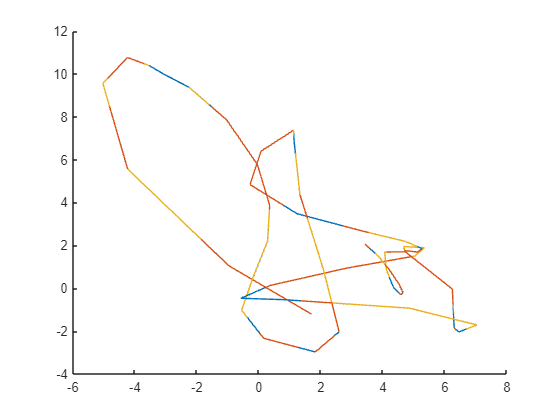


% Plotting sample reference and perturbed states (for 2 ensemble members)
clf
hold on
plot3(X_ref(1, :), X_ref(3, :), X_ref(5, :));
plot3(X_obvs_ens(1, :, 1), X_obvs_ens(2, :, 1), X_obvs_ens(3, :, 1));
plot3(X_obvs_ens(1, :, 2), X_obvs_ens(2, :, 2), X_obvs_ens(3, :, 2));

## **Question 2**

**2.1)**

- Consider the data assimilation problem posed over the interval [0, T], starting with initial background states from N (xb[0] , B0).

- Observations are available at times ti = i ∆t, i = 0, . . . , N, tN = T. Use your synthetic observations, observation error covariance, and observation operator from above.

x0b;
B0;
X_t = mvnrnd(x0b,B0,n_ens).'; % TODO - Unclear if these need to be resampled from this distribution or use the ones from above?

% TODO - are we ment to do this for every timestep in the above
% observation? such that the ensemble size can be altered arbitarily? This
% feels like a repetition - however would also get the covariance B_n for
% every step - this should roughly be the same however as the noise is
% constant for all timesteps??

% For now - lets just use the existing ensmble and see how it works

% X_obvs_ens: ensemble of observations for every timestep
% From this can calculate the covar etc




**2.2)**

- Solve the data assimilation problem using the standard (perturbed observations) version of EnKF.

- You will need to implement the filter, run it, and assess the quality of the results.

% TBD

R = 0.025.^2 * eye(20);% Define this above (observation errors)
X_ens_a = mvnrnd(x0b,B0,n_ens).'; % TODO - Unclear if these need to be resampled from this distribution or use the ones from above?

X_ens_array = zeros(n_states, n_ens, length(time_steps));
X_ens_array(:,:,1) = X_ens_a;
B = cov(X_ens_a.');


for t_id = 1:(length(time_steps)-1)
    
    B = cov(X_ens_a.');
    %cond(B)

    K_t = B * H.' * inv(H * B * H.' + R);  % Kalman gain
    Y_t = squeeze(X_obvs_ens(:,t_id,:)); % Get observations from prior trajectory with observation errors added
    X_ens_a = X_ens_a + K_t * (Y_t - H * X_ens_a);   % Caclulate innovation factor and update 
    
    % Move forward in time via model
    for i = 1:n_ens
        [~, x] = ode45(m.RHS.F, [time_steps(t_id) time_steps(t_id)+dt], X_ens_a(:, i));
        X_ens_a(:, i) = x(end, :).';
        X_ens_array(:,i,t_id+1) = X_ens_a(:, i);
    end
    time_steps(t_id)
end

ans = 0

ans = 0.1000

ans = 0.2000

ans = 0.3000

ans = 0.4000

ans = 0.5000

ans = 0.6000

ans = 0.7000

ans = 0.8000

ans = 0.9000

ans = 1

ans = 1.1000

ans = 1.2000

ans = 1.3000

ans = 1.4000

ans = 1.5000

ans = 1.6000

ans = 1.7000

ans = 1.8000

ans = 1.9000

ans = 2

ans = 2.1000

ans = 2.2000

ans = 2.3000

ans = 2.4000

ans = 2.5000

ans = 2.6000

ans = 2.7000

ans = 2.8000

ans = 2.9000

ans = 3

ans = 3.1000

ans = 3.2000

ans = 3.3000

ans = 3.4000

ans = 3.5000

ans = 3.6000

ans = 3.7000

ans = 3.8000

ans = 3.9000

ans = 4

ans = 4.1000

ans = 4.2000

ans = 4.3000

ans = 4.4000

ans = 4.5000

ans = 4.6000

ans = 4.7000

ans = 4.8000

ans = 4.9000


% Plotting sample reference and perturbed states (for 2 ensemble members)
clf
hold on


state_id = 20

state_id = 20

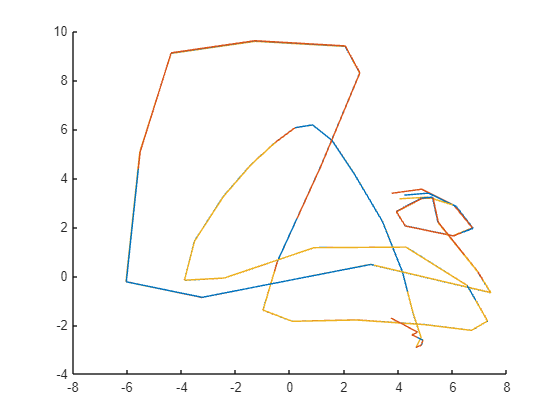

plot3(X_ref(state_id, :), X_ref(state_id+2, :), X_ref(state_id+4, :));
%plot3(X_ens_array(1, 1, :), X_ens_array(2, 1, :), X_ens_array(3, 1, :));
plot3(squeeze(X_ens_array(state_id, 1, :)), squeeze(X_ens_array(state_id+2, 1, :)),squeeze(X_ens_array(state_id+4, 1, :)))
plot3(squeeze(X_ens_array(state_id, 2, :)), squeeze(X_ens_array(state_id+2, 2, :)),squeeze(X_ens_array(state_id+4, 2, :)))

% Calculating accuracy of the ensemble

X_ens_mean = squeeze(mean(X_ens_array, 2))

X_ens_mean =     3.5179    3.8508    4.2258    4.5085    4.6521    4.5787    4.3373    4.1227    4.0690    4.7441    6.2569    6.3058    6.4493    7.0289    4.8345    0.7879   -0.5895    0.3577    2.8282    5.0278    5.3396    4.6760    4.7017    5.1306    5.2609    4.7277    3.3117    1.2322   -0.2811    0.0778    1.1193    1.1339    1.3250    2.0776    2.5881    1.8093    0.1389   -0.5667   -0.1638    0.2905    0.3615   -0.0414   -1.0474   -2.2741   -3.0392   -3.5547   -4.2525   -5.0442   -4.2246   -0.9607
    5.0596    6.0021    6.7197    7.2597    7.6202    7.9297    8.2897    8.7787    9.4183    9.9121    9.7064    8.9684    7.5869    3.9990   -0.5778   -1.8879   -0.8877    0.0467   -0.0029   -1.5125   -2.8640   -3.2499   -2.9411   -1.9921   -1.0413   -0.3704    0.1112    0.6791    1.3724    1.8919    3.0540    4.5206    5.5865    6.0804    5.1443    3.2243    2.5910    3.4783    4.2971    4.5853    4.6974    4.9255    5.2469    5.0247    3.8046    2.1445    0.2433   -2.2289   -4.

clf
hold on
state_id = 15

state_id = 15

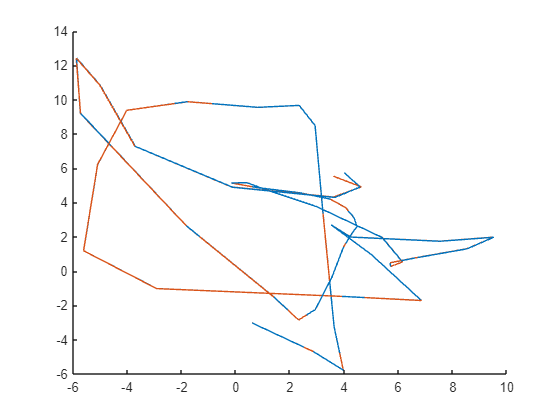

plot3(X_ref(state_id, :), X_ref(state_id+2, :), X_ref(state_id+4, :));
plot3(X_ens_mean(state_id, :), X_ens_mean(state_id+2, :), X_ens_mean(state_id+4, :));

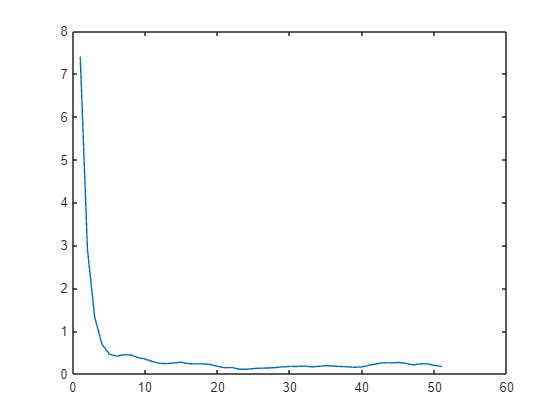

norm_1 = vecnorm(X_ref-X_ens_mean, 1, 1);
norm_2 = vecnorm(X_ref-X_ens_mean, 2, 1);
norm_inf = vecnorm(X_ref-X_ens_mean, Inf, 1);
clf
plot(norm_1)

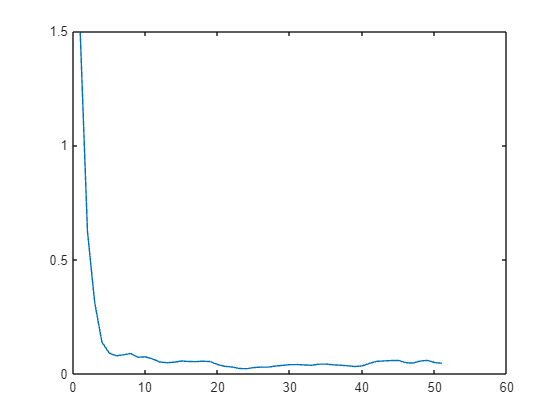

plot(norm_2)

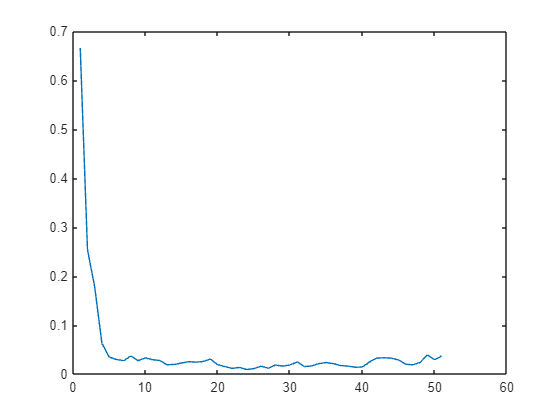

plot(norm_inf)

**2.3)**

- Solve the data assimilation problem using a square root filter (EnSRF), e.g., ETKF.

- You will need to implement the filter, run it, and assess the quality of the results.

% TBD

% R = 0.025.^2 * eye(20);% Define this above (observation errors)
% X_ens_a = mvnrnd(x0b,B0,n_ens).'; % TODO - Unclear if these need to be resampled from this distribution or use the ones from above?
%{
X_ens_array = zeros(n_states, n_ens, length(time_steps));
X_ens_array(:,:,1) = X_ens_a;
B = cov(X_ens_a.');

test_decomp = chol(R);

C_ens = 1/(sqrt(n_ens-1));
x_mean_i = mean(X_ens_a, 2);

X_dot_i = C_ens*(X_ens_a - x_mean_i);
Z_dot_i = H * X_dot_i;

P_b_i = X_dot_i * X_dot_i.';

cov(X_ens_a.'); % Confirming these are the same
[Q, S, ~] = svd(Z_dot_i.'*inv(R)*Z_dot_i);
T = Q*sqrt(eye(n_ens)+S)*Q.';

X_dot_a = X_dot_i * T;

K_test = X_dot_i * inv(eye(n_ens) + Z_dot_i.' * R * Z_dot_i) * Z_dot_i.' * inv(R);
E_i = mvnrnd(zeros(20 ,1).', eye(20)*0.025^2, 100).';
X_dot_a = X_dot_i * T + K_test * (C_ens * E_i);
%}

X_ens_a = mvnrnd(x0b,B0,n_ens).'; % TODO - Unclear if these need to be resampled from this distribution or use the ones from above?

X_ens_array = zeros(n_states, n_ens, length(time_steps));
X_ens_array(:,:,1) = X_ens_a;

X_ens_b = X_ens_a;

C_ens = 1/(sqrt(n_ens-1));
R = 0.025.^2 * eye(20);% Define this above (observation errors)
E_i = mvnrnd(zeros(20 ,1).', eye(20)*0.025^2, n_ens).';

for t_id = 1:(length(time_steps)-1)
    
    x_mean_b = mean(X_ens_b, 2);
    z_mean_b = mean(H*X_ens_b, 2);

    X_dot_b = C_ens*(X_ens_b - x_mean_b);
    Z_dot_b = C_ens*(H*X_ens_b - z_mean_b);  % (3.27)

    % Get observations for current timestep
    Y = X_obvs(:, t_id); % Rename X_obvs_ens -> Y_obvs_ens
    
    % Calculate Transform matrix
    [U, D] = eig(Z_dot_b.' * inv(R) * Z_dot_b);  %(3.61) - inv is frowned upon
    T = real(U) * (eye(n_ens) + real(D))^(-0.5) * real(U).';  % (3.62)

    % Caclualte Kalman gain
    K = X_dot_b * inv(eye(n_ens) + Z_dot_b.' * inv(R) * Z_dot_b) * Z_dot_b.' * inv(R);  %(3.51a)  - inv is frowned upon
    K = X_dot_b * T * T.' * Z_dot_b.' * inv(R);  %(3.51a) %Aparently I can use T to calculate this? More than current?

    % Update ensemble mean
    x_mean_a = x_mean_b + K * (Y - z_mean_b);  %(3.51a)

    % Update the ensemble of scaled deviations
    X_dot_a = X_dot_b * T;  % (3.62)

    % Recreate the ensemble
    X_ens_a = x_mean_a + C_ens.^-1 * X_dot_a;

    % Move forward in time via model
    for i = 1:n_ens
        [~, x] = ode45(m.RHS.F, [time_steps(t_id) time_steps(t_id)+dt], X_ens_a(:, i));
        X_ens_b(:, i) = x(end, :).';  % New prior
        X_ens_array(:,i,t_id+1) = X_ens_b(:, i);  % Save enemble of priors
    end
    time_steps(t_id)
end

ans = 0

ans = 0.1000

ans = 0.2000

ans = 0.3000

ans = 0.4000

ans = 0.5000

ans = 0.6000

ans = 0.7000

ans = 0.8000

ans = 0.9000

ans = 1

ans = 1.1000

ans = 1.2000

ans = 1.3000

ans = 1.4000

ans = 1.5000

ans = 1.6000

ans = 1.7000

ans = 1.8000

ans = 1.9000

ans = 2

ans = 2.1000

ans = 2.2000

ans = 2.3000

ans = 2.4000

ans = 2.5000

ans = 2.6000

ans = 2.7000

ans = 2.8000

ans = 2.9000

ans = 3

ans = 3.1000

ans = 3.2000

ans = 3.3000

ans = 3.4000

ans = 3.5000

ans = 3.6000

ans = 3.7000

ans = 3.8000

ans = 3.9000

ans = 4

ans = 4.1000

ans = 4.2000

ans = 4.3000

ans = 4.4000

ans = 4.5000

ans = 4.6000

ans = 4.7000

ans = 4.8000

ans = 4.9000

X_ens_mean = squeeze(mean(X_ens_array, 2))

X_ens_mean =     3.4958    3.8489    4.2210    4.5030    4.6477    4.5757    4.3327    4.1156    4.0546    4.7209    6.2374    6.2964    6.4431    7.0273    4.8464    0.7952   -0.5864    0.3586    2.8257    5.0247    5.3376    4.6749    4.7012    5.1300    5.2598    4.7255    3.3080    1.2270   -0.2895    0.0676    1.1168    1.1326    1.3206    2.0715    2.5846    1.8148    0.1508   -0.5615   -0.1697    0.2769    0.3465   -0.0507   -1.0464   -2.2636   -3.0225   -3.5388   -4.2381   -5.0368   -4.2366   -0.9721
    5.0896    5.9271    6.7379    7.2321    7.5990    7.9065    8.2692    8.7686    9.4208    9.9211    9.7212    8.9800    7.5943    4.0071   -0.5710   -1.8921   -0.8924    0.0414   -0.0064   -1.5131   -2.8637   -3.2505   -2.9417   -1.9932   -1.0429   -0.3718    0.1110    0.6799    1.3724    1.8874    3.0461    4.5153    5.5820    6.0782    5.1493    3.2312    2.5883    3.4678    4.2910    4.5887    4.7100    4.9413    5.2579    5.0301    3.8096    2.1553    0.2630   -2.2039   -4.

clf
hold on
state_id = 15

state_id = 15

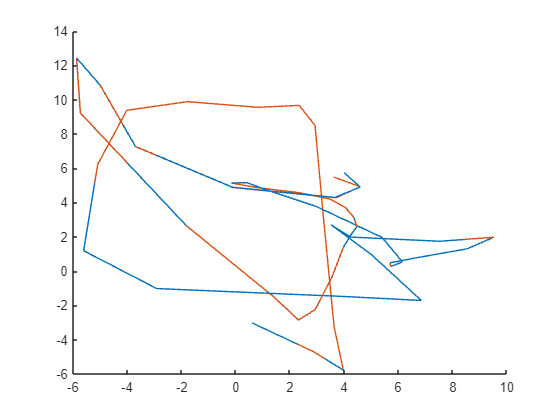

plot3(X_ref(state_id, :), X_ref(state_id+2, :), X_ref(state_id+4, :));
plot3(X_ens_mean(state_id, :), X_ens_mean(state_id+2, :), X_ens_mean(state_id+4, :));

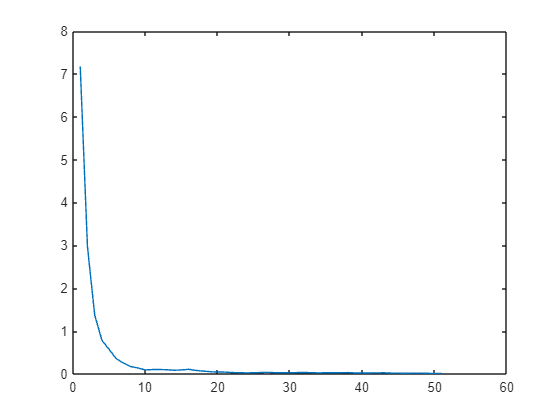

norm_1 = vecnorm(X_ref-X_ens_mean, 1, 1);
norm_2 = vecnorm(X_ref-X_ens_mean, 2, 1);
norm_inf = vecnorm(X_ref-X_ens_mean, Inf, 1);
clf
plot(norm_1)

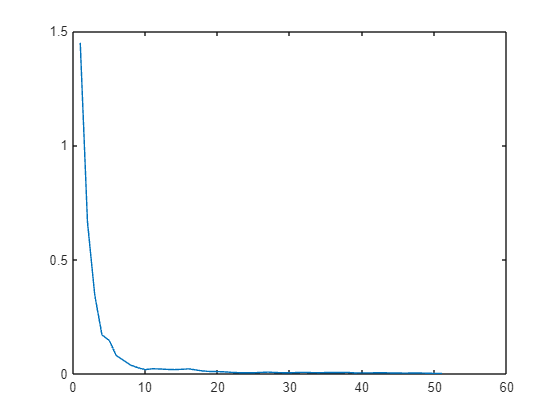

plot(norm_2)

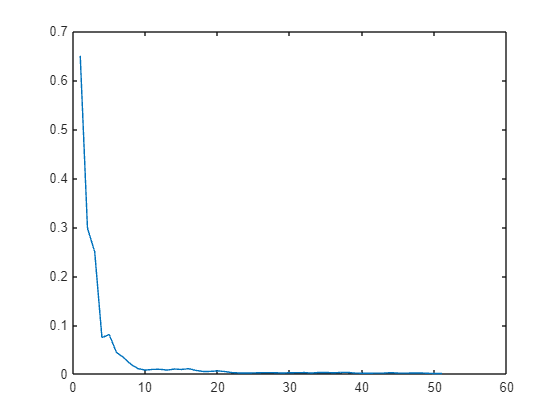

plot(norm_inf)

**2.4)**

For each case plot: 

- The time evolution of the error in the analysis ensemble mean, compared to the reference trajectory.

- The rank histogram for one of the observations.

% - First point is done (?)
% - Unsure about rank histograms (TBD)

**2.5)**

- Apply covariance localization. Use a Gaspari-Cohn function with a decorrelation parameter L = 5.

- Repeat the EnKF and ETKF numerical experiments and compare the results against the analysis obtained without localization.

% TBD

**2.6)**

- In addition to localization, apply multiplicative covariance inflation with a parameter α = 1.02.

-  Again, repeat the EnKF and ETKF numerical experiments, and compare the results against the analysis obtained before. 

% TBD